# Constraint Analysis Walkthrough — L1 disciplines

This live script builds the F-16A constraint diagram with the **Level-1 (L1)** discipline models. It shows how the aerodynamics model and the propulsion model feed the diagram. It then finds the optimum wing loading and thrust-to-weight.

Constraint analysis answers one question. Which combinations of wing loading $ W/S $ and thrust-to-weight $ T/W $ let the aircraft meet every performance requirement at the same time? Each requirement draws one curve. A feasible design sits above every producer curve and to the left of every wall. The best design is the point on the envelope with the smallest $ T/W $, because that point needs the smallest engine.

Method reference: Raymer, *Aircraft Design: A Conceptual Approach*, 6th ed., ch. 5. The per-condition thrust equation is the Mattingly master equation (*Aircraft Engine Design*, 2nd ed., Eq. 2.9 drag polar; master-equation form in ch. 2).

This walkthrough does the following steps:

- it builds the L1 aerodynamics and propulsion models

- it shows the drag polar and the thrust lapse that the models produce

- it assembles the eight F-16A constraint conditions

- it plots each constraint curve and their envelope

- it reads off the optimum design point

The coupled sizing loop ties this diagram to the mission and the weights. That loop is a separate pass. It is not shown here.

## Make the sizing framework visible

This block adds the framework to the MATLAB path. If you already ran `tests/run_all_tests`, the path is set and this block does nothing.

if isempty(which("f16a_spec_path"))
    try
        here = fileparts(matlab.desktop.editor.getActiveFilename);
    catch
        here = pwd;
    end
    root = here;
    while ~isfolder(fullfile(root, "src")) || ~isfolder(fullfile(root, "examples", "F16A"))
        parent = fileparts(root);
        if strcmp(parent, root)
            error("Could not find the sizing/ root. Add its src/, examples/, and VnV/ folders to the path, or run this file from inside air_vehicle_design/sizing.");
        end
        root = parent;
    end
    addpath(genpath(fullfile(root, "src")));
    addpath(genpath(fullfile(root, "examples")));
    addpath(genpath(fullfile(root, "VnV")));
end

## Build the L1 discipline models

The constraint analysis needs two discipline objects. The aerodynamics object gives the drag polar and the maximum lift. The propulsion object gives the thrust lapse and the sea-level thrust. Each object reads its inputs from the unified L1 input file, `f16a_L1.json`, through the path helper `f16a_spec_path(1)`.

Note one point. The geometry object is **not** injected into the constraint analysis. Wing loading $ W/S $ is the horizontal axis, so the reference area enters through that axis, not through a geometry object. At L1 the wing aspect ratio and sweep are spec scalars that live on the aero object itself.

aero = F16AeroL1(f16a_spec_path(1));
prop = F16PropL1(f16a_spec_path(1));

## What the models produce

The analysis builds its own atmosphere state for each condition. Here we build one example state, cruise at 36,000 ft and Mach 0.87, only to show what the models return at a single point.

state = AircraftState(36000, 0.87);
state

state =   AircraftState with properties:

    altitude_ft: 36000
           mach: 0.8700
          T_atm: 390.2882
          P_atm: 474.7109
            rho: 7.0857e-04
              a: 968.4707
              V: 842.5695
              q: 251.5161
          theta: 0.7525
          delta: 0.2243
        theta_0: 0.8664
        delta_0: 0.3674


The aerodynamics object returns the drag polar $ C_D = C_{D0} + K_1 C_L^2 + K_2 C_L $ and the maximum lift coefficients. The takeoff and landing rows add the gear and flap drag and lift increments.

polar = aero.drag_polar(state);
aeroValues = [polar.CD0; polar.K1; polar.K2; aero.get_CLmax(state); ...
    aero.get_CLmax_TO(); aero.get_CLmax_L(); aero.get_Delta_CD0_TO(); aero.get_Delta_CD0_L()];
aeroSummary = table(aeroValues, 'VariableNames', "Value", 'RowNames', ...
    {'CD0  zero-lift drag', 'K1  induced-drag factor', 'K2  camber term', ...
     'CLmax  clean', 'CLmax  takeoff', 'CLmax  landing', ...
     'dCD0  takeoff (gear+flap)', 'dCD0  landing (gear+flap)'})

aeroSummary = 8×1 table
                                  Value 
                                 _______

    CD0  zero-lift drag            0.016
    K1  induced-drag factor      0.11677
    K2  camber term                    0
    CLmax  clean                     1.5
    CLmax  takeoff                   1.7
    CLmax  landing                   2.1
    dCD0  takeoff (gear+flap)      0.035
    dCD0  landing (gear+flap)      0.085


The propulsion object returns the sea-level static thrust and the thrust lapse $ \alpha = T/T_{SL} $, where $ T $ is the thrust at the flight altitude and Mach. The lapse scales the available thrust with altitude and Mach. At L1 the lapse is a density-ratio law.

propSummary = table([prop.T_SL; prop.thrust_lapse(state, "AB")], 'VariableNames', "Value", ...
    'RowNames', {'T_SL  sea-level static thrust [lbf]', 'alpha  thrust lapse at 36 kft / M0.87'})

propSummary = 2×1 table
                                              Value 
                                             _______

    T_SL  sea-level static thrust [lbf]        23770
    alpha  thrust lapse at 36 kft / M0.87    0.48374


The next table maps each model output to the place where it enters the diagram.

## Assemble the constraint analysis

`ConstraintAnalysis.from_requirements` reads the eight F-16A conditions from `f16a_requirements.json`. It injects the aero and prop objects into every condition. `F16ConstraintSet.constraint_map()` says which constraint class models each named condition. `PointPerformanceBase.WS_RANGE_BRANDT` is the wing-loading sweep, 20 to 160 psf.

ca = ConstraintAnalysis.from_requirements(aero, prop, f16a_requirements_path(), ...
    F16ConstraintSet.constraint_map(), PointPerformanceBase.WS_RANGE_BRANDT);

The conditions split into two kinds. A **producer** supplies a required `T/W` curve. A **wall** supplies an upper `W/S` limit and no thrust demand. For the F-16 set, seven conditions are producers and Landing is the one wall. Stall is left out on purpose, because at this fidelity its wall would bind the optimum too early.

nC = numel(ca.constraints);
condName = strings(nC,1); condClass = strings(nC,1); condRole = strings(nC,1);
for i = 1:nC
    c = ca.constraints{i};
    condName(i)  = c.name;
    condClass(i) = string(class(c));
    if isa(c, 'Only_WbyS'), condRole(i) = "W/S wall"; else, condRole(i) = "T/W producer"; end
end
conditions = table(condName, condClass, condRole, 'VariableNames', ["Condition", "ConstraintClass", "Role"])

conditions = 8×3 table
             Condition                   ConstraintClass              Role     
    ____________________________    _________________________    ______________

    "Max Mach"                      "LevelFlightConstraint"      "T/W producer"
    "Cruise"                        "LevelFlightConstraint"      "T/W producer"
    "Max Alt"                       "LevelFlightConstraint"      "T/W producer"
    "Combat Turn 1 (subsonic)"      "SustainedTurnConstraint"    "T/W producer"
    "Combat Turn 2 (supersonic)"    "SustainedTurnConstraint"    "T/W producer"
    "Excess Power"                  "ExcessPowerConstraint"      "T/W producer"
    "Takeoff"                       "TakeoffConstraint"          "T/W producer"
    "Landing"                       "LandingConstraint"          "W/S wall"    


## Individual constraint curves and their envelope

Each producer condition demands a minimum `T/W` at every `W/S`. The design must beat all of them, so the binding demand is the pointwise maximum. That maximum is the envelope, drawn as the thick black line. The vertical dashed line is the Landing `W/S` wall. The optimum sits at the lowest point of the envelope that is still left of the wall.

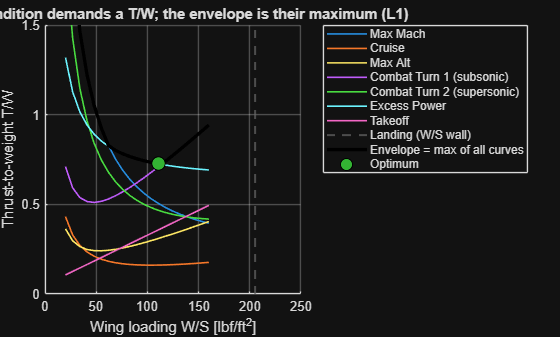

WS = ca.WS_range;
hold on
for i = 1:nC
    c = ca.constraints{i};
    if isa(c, 'Only_WbyS')
        xline(c.WS_max(), '--', 'Color', [0.4 0.4 0.4], 'LineWidth', 1.5, 'DisplayName', c.name + " (W/S wall)");
    else
        plot(WS, c.required_TW(WS), 'LineWidth', 1.2, 'DisplayName', c.name);
    end
end
plot(WS, ca.envelope(), 'k', 'LineWidth', 2.5, 'DisplayName', 'Envelope = max of all curves');
[WS_opt, TW_opt] = ca.optimal_point();
plot(WS_opt, TW_opt, 'o', 'MarkerSize', 10, 'MarkerFaceColor', [0.2 0.7 0.2], 'MarkerEdgeColor', 'k', 'DisplayName', 'Optimum');
hold off
grid on
xlabel('Wing loading W/S [lbf/ft^2]')
ylabel('Thrust-to-weight T/W')
title('Each condition demands a T/W; the envelope is their maximum (L1)')
legend('Location', 'northeastoutside')
ylim([0 1.5])

## The constraint diagram and the optimum

`plot_diagram` draws the same information as a finished diagram. It shades the feasible region, draws each curve and wall, and marks the optimum design point.

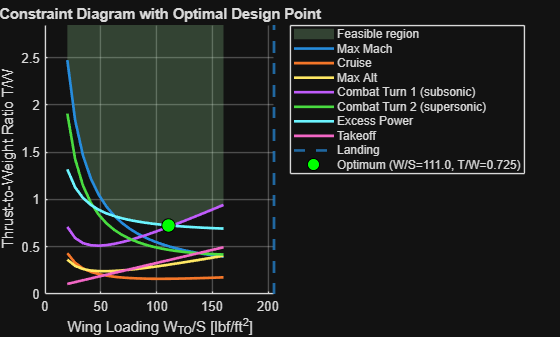

ca.plot_diagram();

`optimal_point` returns the numbers. The optimum is the smallest-engine design that still meets every requirement.

[WS_opt, TW_opt] = ca.optimal_point();
optimum = table(WS_opt, TW_opt, 'VariableNames', ["WS_opt_lbf_per_ft2", "TW_opt"])

optimum = 1×2 table
    WS_opt_lbf_per_ft2    TW_opt 
    __________________    _______

           111            0.72531


## Summary

The L1 aerodynamics model set the drag and lift of every curve. The L1 propulsion model set the thrust lapse and the thrust datum. Together they placed the eight conditions on the `T/W`-vs-`W/S` plane, and the envelope gave the optimum design point.

The optimum here is one point. The coupled sizing loop holds this design point fixed while it iterates the weight and the mission. That loop is a separate pass and is not shown in this script.

To run the same study at higher fidelity, open `constraint_analysis_highfidelity_walkthrough.mlx`. It swaps the three L1 constructor lines for the L3 stack.